# `LGBeam.m`

[`LGbeam(p, l, w_0, z, lambda, rho, theta)`](matlab:open('..\optics\LGBeam.m')) 是一个复数标量函数，主要用于计算拉盖尔-高斯光束（`LGBeam`）场振幅的分布[[1](https://doi.org/10.1016/0030-4018(93)90535-D),[2](https://en.wikipedia.org/wiki/Gaussian_beam#Laguerre-Gaussian_modes)]。

% 版本:      v1.0.1
% 创建时间:  2023.03.10
% 修改时间:  2023.03.12
% 作者:      yi_Xu
% 邮箱:      yi_Xu@yixuju.cn

`----------------------------------------------------------------------------------------------------`

## 基本参数

[`LGBeam`](matlab:open('..\optics\LGBeam.m')) 函数描述了满足准轴近似下的波动方程并受以下输入参数限制的拉盖尔-高斯光束场振幅分布：

p = 0;                 % 径向量子数
l = 0;                 % 角向量子数
w_0 = 5e-4;            % 光束束腰尺寸
z = 0;                 % 传播距离
lambda = 5e-7;         % 光束波长

而为了获得柱坐标系下的半径和角度，可以使用 [`cart2pol(x, y)`](https://www.mathworks.com/help/releases/R2022b/matlab/ref/cart2pol.html) 函数

L = 10e-3;
N = 1000;
xoy = linspace(-0.5 * L, 0.5 * L, N);
[X, Y] = meshgrid(xoy, xoy);
% 获取柱坐标系下，半径 rho 和角度 theta
[theta, rho] = cart2pol(X, Y);

`----------------------------------------------------------------------------------------------------`

## `LG`光束场分布计算过程

拉盖尔-高斯光束场振幅分布通过以下公式得到: 


$$u(r, \phi, z) = C_{l p}^{L G} \frac{1}{w(z)}\left(\frac{r \sqrt{2}}{w(z)}\right)^{|l|} \exp \left(-\frac{r^{2}}{w^{2}(z)}\right) L_{p}^{|l|}\left(\frac{2 r^{2}}{w^{2}(z)}\right) 
 \exp \left(-i k \frac{r^{2}}{2 R(z)}\right) \exp (-i l \phi) \exp (i \psi(z))$$


其中， $C_{l p}^{L G}$ 是`归一化常数，由 `$\int_{0}^{2 \pi} d \phi \int_{0}^{\infty} r d r|u(r, \phi, z)|^{2}=1$得到：$C_{l p}^{L G}=\sqrt{\frac{2 p !}{\pi(p+|l|) !}}$

$w(z)$ 是[光束尺寸](https://en.wikipedia.org/wiki/Gaussian_beam#Beam_waist)，并由 $w(z)=w_{0} \sqrt{1+\left(\frac{z}{z_{\mathrm{R}}}\right)^{2}}$得到，

其中 $z_{\mathrm{R}}$ 是瑞利范围，并由 $z_{\mathrm{R}}=\frac{\pi w_{0}^{2} n}{\lambda}$ 得到。其中，$w_0$ 是光束束腰尺寸， $n$ 为介质折射率， $\lambda$ 是光波长。

$ L_{p}^{|l|}(x)$ 是[广义拉盖尔多项式](https://en.wikipedia.org/wiki/Laguerre_polynomials#Generalized_Laguerre_polynomials)，可以使用 [`laguerre(p, `$|l|$`, x)`](matlab:open('..\common\laguerre.m')) 函数得到。

$R(z)$ 是[波前曲率](https://en.wikipedia.org/wiki/Gaussian_beam#Wavefront_curvature)，由 $R(z)=z\left[1+\left(\frac{z_{\mathrm{R}}}{z}\right)^{2}\right]$ 得到。

$\psi(z)$是[***Gouy ***相位](https://en.wikipedia.org/wiki/Gaussian_beam#Gouy_phase)，是光波经过其束腰时产生的轴向相移，由 $\psi(z)=\arctan \left(\frac{z}{z_{\mathrm{R}}}\right)$ 得到。

综上，我们可以通过 [`LGBeam`](matlab:open('..\optics\LGBeam.m')) 函数获得了拉盖尔高斯光的光场振幅分布。

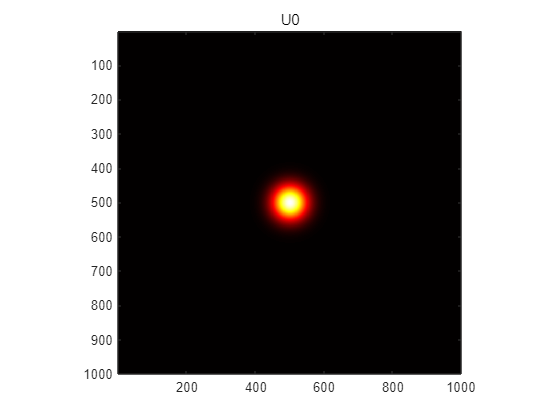

U0 = LGBeam(p,l,w_0,z,lambda,rho,theta);
% 绘制光场分布图
figure
imagesc(abs(U0))
title("U0")
colormap hot
axis square

`----------------------------------------------------------------------------------------------------`

## `p` 量子数和 `l` 量子数对光束分布的影响

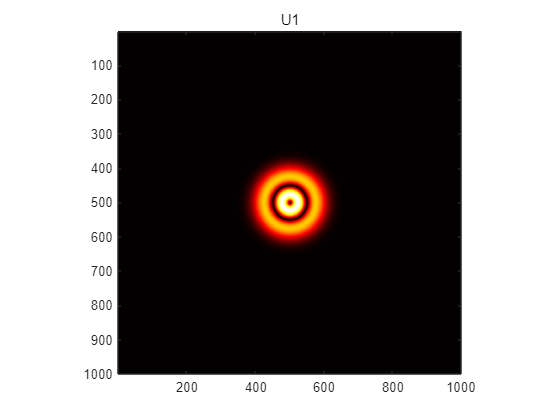

p1 = 1;
l1 = 1;
U1 = LGBeam(p1,l1,w_0,z,lambda,rho,theta);
% 绘制光场分布图
figure
imagesc(abs(U1))
title("U1")
colormap hot
axis square

`----------------------------------------------------------------------------------------------------`

## 参考链接

- [`https://doi.org/10.1016/0030-4018(93)90535-D`](https://doi.org/10.1016/0030-4018(93)90535-D)

- [`https://en.wikipedia.org/wiki/Gaussian_beam#Laguerre-Gaussian_modes`](https://en.wikipedia.org/wiki/Gaussian_beam#Laguerre-Gaussian_modes)